clear; clc;
close all;
addpath('../functions', '../data')
load proj23.mat
load rain_rec.mat

% Load data
load transformed2.mat
load BJmodel_light.mat
t_int = ElGeneina.rain_t;
t_org= ElGeneina.rain_org_t;
ndvi = ElGeneina.nvdi;
% rescale the vegitation data so it is between -1 and 1
rendvi = (ndvi/255)*2 -1;
t_ndvi = ElGeneina.nvdi_t;

% Splitting to trainng validation and testingr4e5
t = t_int(793:end);
x = transformed_rain2(793:end)'; % use for model 1 and 2
x = log(x+6); %
y = log(rendvi); %

% data split
trainx = x(1:450);
validx = x(451:551);
testx = x(552:end);


trainn = y(1:450);
validn = y(451:551);
testn = y(552:end);

train_t = t(1:450);
valid_t = t(451:551);
test_t = t(552:end);

% Use all data here
y = [trainn;validn;testn];
my = mean(y);
y = y-my;
x = [trainx;validx;testx]; x= x-mean(x);
validstart = train_t(end);
t0 = [train_t;valid_t;test_t];
N = length(y);

% Naive predictions:
y_naive = [zeros(1,36)' ; y(1:N-36)];
plot(y)
hold on 
plot(y_naive)
hold off
legend('data','naive prediction')


A3 =  [1.0000         0   -0.3556];
C3 = [1.0000    0.4197   -0.2128];
x = y;

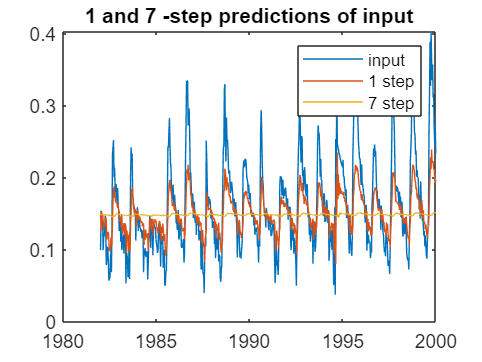

% Predict the output using the found model. (non-adaptive/ polynomial division predictions)
k = 7;
xhatk = zeros(k,length(x));
yhatk = zeros(k,length(y));
for r=1:k
    [Fx, Gx] = polydiv( C3, A3, r );
    xhatk(r,:) = filter(Gx, C3, x);
end

% plot predictions
s1= 1;
s2 = k;
figure
plot(t,exp(x+my))
hold on
plot(t,exp(xhatk(s1,:)+my))
plot(t,exp(xhatk(s2,:)+my))
hold off
legend('input',sprintf('%d step ',s1),sprintf('%d step',s2))
title(sprintf('%d and %d -step predictions of input',s1,s2))